# Evaluación

Ana Itzel Hernández García A01737526

Obtener la **cinemática directa** del  robot:

- **Obtener **el vector de velocidades lineales y el vector de velocidades angulares para los siguientes robots manipuladores

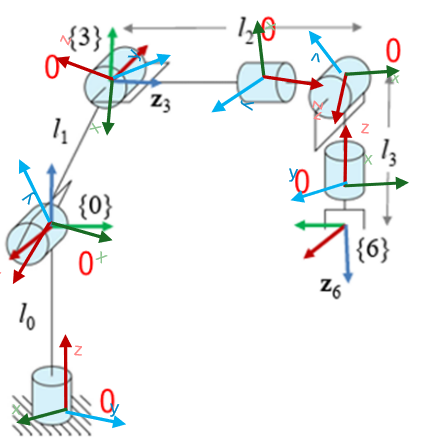

Se limpian las variables

clear all
close all
clc

Delcaración de variables simbólicas (**6 grados libertad**)

syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) l0 l1 l2 l3 l4 l5 t

% Configuración del robot, de cada GDL
RP = [0, 0, 0, 0, 0, 0];

% Creación del vector de coordenadas articulares
Q = [th1, th2, th3, th4, th5, th6];

% Creación del vector de velocidades generalizadas
Qp = diff(Q, t);

% Número de grados de libertad
GDL = size(RP, 2);
GDL_str = num2str(GDL);

## Articulación 1

Posición de la articulación 1 a 2

Debido a que cuenta con una traslación en el eje z se toma en cuenta la longitud que se encuentra en ese eje, es decir l0

P(:,:,1) = [
             0;
             0;
             l0
           ];

Matriz de rotación de la junta 1 a 2

A la matriz de rotación Z se le realiza una transfromación con una rotación de 180° positivos en Y 

R(:,:,1) = [
             cos(th1)   -sin(th1)     0;
             sin(th1)    cos(th1)     0;
             0           0            1
             ]*rotY(180);

## Articulación 2

Posición de la articulación 2 a 3

Como la rotación afecta la posición de la articulación 2 entonces usamos la forma: longitud * cos(angulo) en X , longitud * sen(angulo) en Y

P(:,:,2) = [
            l1*cos(th2);
            l1*sin(th2);
            0
           ];

Matriz de rotación 2 a 3

A la matriz de rotación Z se le realiza una transfromación con una rotación de 90° negativos en Y 

R(:,:,2) = [
             cos(th2)   -sin(th2)     0;
             sin(th2)    cos(th2)     0;
             0           0            1
             ]*rotY(-90); 

## Articulación 3

Posición de la articulación 3 respecto a la 4

Como la rotación afecta la posición de la articulación 2 entonces usamos la forma: longitud * cos(angulo) en X , longitud * sen(angulo) en Y

P(:,:,3) = [
             l2*cos(th3);
             l2*sin(th3);
             0
           ];


Matriz de rotación de la junta 3 respecto a 2 0°

A la matriz de rotación Z se le realiza una transfromación con una rotación de 180° negativos en Y 

R(:,:,3) = [
             cos(th3)   -sin(th3)     0;
             sin(th3)    cos(th3)     0;
             0           0            1
             ]*rotY(-180);

## Articulación 4

Posición de la articulación 4 respecto a la 5

Como la rotación afecta la posición de la articulación 4 entonces usamos la forma: longitud * cos(angulo) en X , longitud * sen(angulo) en Y

% Posición de la articulación 4 a 5
P(:,:,3) = [
             l3*sin(th4);
             l3*cos(th4);
             0
           ];


Matriz de rotación de la junta 4 respecto a 5

A la matriz de rotación Z se le realiza una transfromación con una rotación de 90° positivos en Y 

% Matriz de rotación de la junta 4 a 5
R(:,:,4) = [
             cos(th4)   -sin(th4)     0;
             sin(th4)    cos(th4)     0;
             0           0            1
             ]*rotY(90);

## Articulación 5

Posición de la articulación 5 respecto a la 6

Como la rotación afecta la posición de la articulación 4 entonces usamos la forma: longitud * cos(angulo) en X , longitud * sen(angulo) en Y

% Posición de la articulación 5 a 6
P(:,:,5) = [
            l4*sin(th5);
            l4*cos(th5);
            0
           ];

Matriz de rotación de la junta 5 respecto a 6

A la matriz de rotación Z se le realiza una transfromación con una rotación de 90° negativos en X 


% Matriz de rotación de la junta 5 a 6
R(:,:,5) = [
             cos(th5)   -sin(th5)     0;
             sin(th5)    cos(th5)     0;
             0           0            1
             ]*rotX(-90);

## Articulación 6

Posición de la articulación 6

Debido a que cuenta con una traslación en el eje z se toma en cuenta la longitud que se encuentra en ese eje, es decir l5

% Posición de la articulación 6
P(:,:,6) = [
            0;
            0;
            l5
           ];

Matriz de rotación de la junta 6 

A la matriz de rotación Z se mantiene debido a que no hay ninguna transformación


% Matriz de rotación de la junta 6
R(:,:,6) = [
             cos(th6)   -sin(th6)     0;
             sin(th6)    cos(th6)     0;
             0           0            1
             ];

## Matrices

% Creación de vector de ceros
vector_zeros = zeros(1,3);

% Inicialización de las matrices de Transformación Homogenea locales
A(:, :, GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de las matrices de tranformación Homogenea globales
T(:,:,GDL) = simplify([ ...
                        R(:,:,GDL)      P(:,:,GDL); ...
                        vector_zeros    1 ...
                        ]);

% Inicialización de los vectores de posición vistos desde el marco de
% referencia inercial
PO(:,:,GDL) = P(:,:,GDL);

% Inicialización de las matrices de rotación vistas desde el marco de
% referencia inercial
RO(:,:,GDL) = R(:,:,GDL);

for i = 1:GDL
    i_str = num2str(i);

    % Locales
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i) = simplify([ ...
                         R(:,:,i)       P(:,:,i); ...
                         vector_zeros   1 ...
                        ]); A(:,:,i)

    % Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i); % Caso específico cuando i=1 nos marcaría error en try
    end

    disp(strcat('Matruz de Transformación global T', i_str));
    T(:,:,i) = simplify(T(:,:,i)); T(:,:,i)

    % Obtención de la matriz de rotación "RO" y el vector de traslación PO
    % de la matriz de transformación homogenea global T(:,:, GDL)
    RO(:,:,i) = T(1:3,1:3,i);
    PO(:,:,i) = T(1:3,4,i);
end

Matriz de Transformación local A1


$$ans = \left(\begin{array}{cccc} -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & 0\\ -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & -1 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T1


$$ans = \left(\begin{array}{cccc} -\cos\left({\mathrm{th}}_{1}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & 0\\ -\sin\left({\mathrm{th}}_{1}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)\right) & 0 & 0\\ 0 & 0 & -1 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A2


$$ans = \left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & -\cos\left({\mathrm{th}}_{2}\left(t\right)\right) & l_{1}\,\cos\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & \cos\left({\mathrm{th}}_{2}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{2}\left(t\right)\right) & l_{1}\,\sin\left({\mathrm{th}}_{2}\left(t\right)\right)\\ 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T2


$$ans = \left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right)\right) & \cos\left({\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right)\right) & -l_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right)\right)\\ 0 & \cos\left({\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right)\right) & \sin\left({\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right)\right) & -l_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right)\right)\\ -1 & 0 & 0 & l_{0}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matriz de Transformación local A3


$$ans = \left(\begin{array}{cccc} -\cos\left({\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\sin\left({\mathrm{th}}_{4}\left(t\right)\right)\\ -\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{3}\,\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T3


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sin\left(\sigma_{1}\right)\,\sin\left({\mathrm{th}}_{3}\left(t\right)\right) & -\sin\left(\sigma_{1}\right)\,\cos\left({\mathrm{th}}_{3}\left(t\right)\right) & -\cos\left(\sigma_{1}\right) & -l_{1}\,\cos\left(\sigma_{1}\right)-l_{3}\,\sin\left(\sigma_{1}\right)\,\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\\ -\sin\left({\mathrm{th}}_{3}\left(t\right)\right)\,\cos\left(\sigma_{1}\right) & \cos\left({\mathrm{th}}_{3}\left(t\right)\right)\,\cos\left(\sigma_{1}\right) & -\sin\left(\sigma_{1}\right) & l_{3}\,\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\,\cos\left(\sigma_{1}\right)-l_{1}\,\sin\left(\sigma_{1}\right)\\ \cos\left({\mathrm{th}}_{3}\left(t\right)\right) & \sin\left({\mathrm{th}}_{3}\left(t\right)\right) & 0 & l_{0}-l_{3}\,\sin\left({\mathrm{th}}_{4}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right) \end{array}$$

Matriz de Transformación local A4


$$ans = \left(\begin{array}{cccc} 0 & -\sin\left({\mathrm{th}}_{4}\left(t\right)\right) & \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & 0\\ 0 & \cos\left({\mathrm{th}}_{4}\left(t\right)\right) & \sin\left({\mathrm{th}}_{4}\left(t\right)\right) & 0\\ -1 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T4


$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1}\,\sigma_{4} & \sigma_{1}\,\sigma_{3} & -l_{1}\,\sigma_{2}-l_{3}\,\sigma_{1}\,\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\\ \sigma_{1} & \sigma_{2}\,\sigma_{4} & -\sigma_{3}\,\sigma_{2} & l_{3}\,\cos\left({\mathrm{th}}_{4}\left(t\right)\right)\,\sigma_{2}-l_{1}\,\sigma_{1}\\ 0 & \sigma_{3} & \sigma_{4} & l_{0}-l_{3}\,\sin\left({\mathrm{th}}_{4}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left({\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left({\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right)\right)\\ \sigma_{3}=\sin\left({\mathrm{th}}_{3}\left(t\right)-{\mathrm{th}}_{4}\left(t\right)\right)\\ \sigma_{4}=\cos\left({\mathrm{th}}_{3}\left(t\right)-{\mathrm{th}}_{4}\left(t\right)\right) \end{array}$$

Matriz de Transformación local A5


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{5}\left(t\right)\right) & 0 & -\sin\left({\mathrm{th}}_{5}\left(t\right)\right) & l_{4}\,\cos\left({\mathrm{th}}_{5}\left(t\right)\right)\\ \sin\left({\mathrm{th}}_{5}\left(t\right)\right) & 0 & \cos\left({\mathrm{th}}_{5}\left(t\right)\right) & l_{4}\,\sin\left({\mathrm{th}}_{5}\left(t\right)\right)\\ 0 & -1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T5


Matriz de Transformación local A6


$$ans = \left(\begin{array}{cccc} \cos\left({\mathrm{th}}_{6}\left(t\right)\right) & -\sin\left({\mathrm{th}}_{6}\left(t\right)\right) & 0 & 0\\ \sin\left({\mathrm{th}}_{6}\left(t\right)\right) & \cos\left({\mathrm{th}}_{6}\left(t\right)\right) & 0 & 0\\ 0 & 0 & 1 & l_{5}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Matruz de Transformación global T6


En las matrices locales podemos observar que efectivamente en la ultima columna se respeta el vector de posción, mientas que en global concentra las pocisiones de las articulaciones.

De igual manera las matrices locales contienen cada matriz de rotación 3x3 de cada rotación mientras la global contiene la general del sistema

% Inicialización de jacobianos analíticos (lineal y angular)
Jv_a(:,GDL) = PO(:,:,GDL);
Jw_a(:,GDL) = PO(:,:,GDL);

for k = 1:GDL
    if(RP(k) == 0)
        % Para las articulaciones rotacionales
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), PO(:,:,GDL) - PO(:,:,k-1));
            Jw_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0 0 1], PO(:,:,GDL)); % Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k) = [0 0 1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
    elseif(RP(k) == 1)
        % Para las articulaciones prismáticas
        try
            Jv_a(:,k) = RO(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1]; % Si no hay matriz de rotación previa se obtiene la matriz identidad
        end
            Jw_a(:,k) = [0 0 0];
    end
end

## Despliegue

disp('Jacobiano lineal obtenido de forma analítica'); Jv_a = simplify(Jv_a);

Jacobiano lineal obtenido de forma analítica


disp('Jacobiano angular obtenido de forma ananlítica'); Jw_a = simplify(Jw_a);

Jacobiano angular obtenido de forma ananlítica


disp('Velocidad lineal obtenida mediante el Jacobiano lineal'); V = simplify(Jv_a * Qp')

Velocidad lineal obtenida mediante el Jacobiano lineal


disp('Velocidad angular obtenida mediante el Jacobiano angular'); W = simplify(Jw_a * Qp')

Velocidad angular obtenida mediante el Jacobiano angular


$$W(t) = \begin{array}{l} \left(\begin{array}{c} \sigma_{6}\,\cos\left(\sigma_{4}\right)-\sigma_{1}\,\left(\sin\left({\mathrm{th}}_{5}\left(t\right)\right)\,\cos\left(\sigma_{4}\right)+\sin\left(\sigma_{4}\right)\,\cos\left({\mathrm{th}}_{5}\left(t\right)\right)\,\cos\left(\sigma_{3}\right)\right)-\sigma_{5}\,\cos\left(\sigma_{4}\right)+\sin\left(\sigma_{4}\right)\,\sin\left(\sigma_{3}\right)\,\sigma_{2}\\ \sin\left(\sigma_{4}\right)\,\sigma_{6}-\sigma_{1}\,\left(\sin\left(\sigma_{4}\right)\,\sin\left({\mathrm{th}}_{5}\left(t\right)\right)-\cos\left({\mathrm{th}}_{5}\left(t\right)\right)\,\cos\left(\sigma_{4}\right)\,\cos\left(\sigma_{3}\right)\right)-\sin\left(\sigma_{4}\right)\,\sigma_{5}-\sin\left(\sigma_{3}\right)\,\sigma_{2}\,\cos\left(\sigma_{4}\right)\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}-\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{2}\left(t\right)}+\sigma_{2}\,\cos\left(\sigma_{3}\right)+\sin\left(\sigma_{3}\right)\,\sigma_{1}\,\cos\left({\mathrm{th}}_{5}\left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{6}\left(t\right)}\\ \sigma_{2}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{5}\left(t\right)}\\ \sigma_{3}={\mathrm{th}}_{3}\left(t\right)-{\mathrm{th}}_{4}\left(t\right)\\ \sigma_{4}={\mathrm{th}}_{1}\left(t\right)-{\mathrm{th}}_{2}\left(t\right)\\ \sigma_{5}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{4}\left(t\right)}\\ \sigma_{6}=\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{3}\left(t\right)} \end{array}$$

## Funciones de rotacion

function r_x = rotX(th)
    r_x = [1 0 0; 0 cosd(th) -sind(th); 0 sind(th) cosd(th)];
end

function r_y = rotY(th)
    r_y = [cosd(th) 0 sind(th); 0 1 0; -sind(th) 0 cosd(th)];
end

function r_z = rotZ(th)
    r_z = [cosd(th) -sind(th) 0; sind(th) cosd(th) 0; 0 0 1];
end